# Projekt 13: ***Wyznaczanie kadencji biegowej na podstawie sygnałów akcelerometrycznych, z  wykorzystaniem funkcji autokorelacji***

Wyznaczanie chwilowej kadencji biegowej/chodu (liczby kroków na minutę) na podstawie  sygnałów przyspieszeń ciała przy pomocy funkcji autokorelacji. Należy zastosować techniki zwiększające rozdzielczość wyznaczania przebiegu kadencji. 

## Załadowanie danych projektowych

load sensorlog_20220307_165621.mat

x = Acceleration.X;
y = Acceleration.Y;
z = Acceleration.Z;
timestamp = Acceleration.Timestamp;

% obliczenie różnicy czasowej między próbkami w [s] i częstotliwości
% próbkowania fs [Hz]
dt = seconds(diff(timestamp));
mean_dt = sum(dt)/length(dt);
fs = 1 / mean_dt;
fprintf('Częstotliwość próbkowania wynosi: %.2f Hz', fs)

Częstotliwość próbkowania wynosi: 52.63 Hz

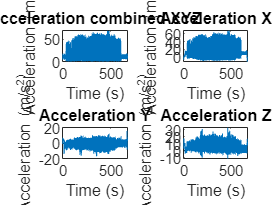

% wyliczenie wypadkowej X, Y i Z
combinedAccel = sqrt(x.^2+y.^2+z.^2);
t = zeros(size(timestamp));

% wektor czasu
for n = 1 : length(timestamp)
  t(n) = seconds(timestamp(n) - timestamp(1));
end

figure,
subplot(2, 2, 1)
plot(t, combinedAccel)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Acceleration combined XYZ')

subplot(2, 2, 2)
plot (t,x)
title('Acceleration X')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

subplot(2, 2, 3)
plot (t,y)
title('Acceleration Y')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

subplot(2, 2, 4)
plot(t, z)
title('Acceleration Z')
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

## Filtracja

Filtracja sygnałów do częstotliwości ograniczonej przez założone wartości kadencji minimalnej i maksymalnej. *(Zakres kadencji przyjąć 60-300 (średnia około 170-200, rekord świata 380))*

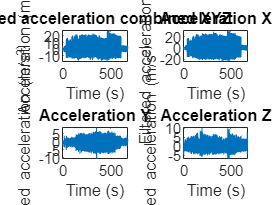

% założone wartości progowe kadencji 
min_cadence = 60;
 min_fs = min_cadence/60;
 max_cadence = 300;
 max_fs = max_cadence/60;

 x = bandpass(x,[min_fs max_fs],fs);
 y = bandpass(y,[min_fs max_fs],fs);
 z = bandpass(z,[min_fs max_fs],fs);
 combinedAccel = bandpass(combinedAccel,[min_fs max_fs],fs);

figure,
subplot(2, 2, 1)
plot(t, combinedAccel)
xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')
title('Filtered acceleration combined XYZ')

subplot(2, 2, 2)
plot (t,x)
title('Acceleration X')
xlabel('Time (s)')
ylabel('Filtered acceleration (m/s^2)')

subplot(2, 2, 3)
plot (t,y)
title('Acceleration Y')
xlabel('Time (s)')
ylabel('Filtered acceleration (m/s^2)')

subplot(2, 2, 4)
plot (t,z)
title('Acceleration Z')
xlabel('Time (s)')
ylabel('Filtered acceleration (m/s^2)')

## Spektrogram

% długość okna
min_W = log2(16);
max_W = log2(1024);
window = 2^7

window = 128

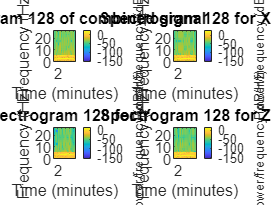

noverlap = int8(0.7*window);
nfft = 1024;
fs1 = fs;
figure,
subplot(2, 2, 1)
spectrogram(combinedAccel, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i of combined signal", window))
subplot(2, 2, 2)
spectrogram(x, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for X", window))
subplot(2, 2, 3)
spectrogram(y, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for Y", window))
subplot(2, 2, 4)
spectrogram(z, window, noverlap, nfft,fs1,'yaxis');  
title(sprintf("Spectrogram %i for Z", window))

## Autokorelacja 

Autokorelacja *(Autokorelacja z przebiegów x lub z combined. Dopasowanie okna autokorelacji (nie za długie, żeby nie wykrywało kilku kroków))*

*Cały sygnał podzielić na kawałki 2s i obliczyć ich korelację z przesunięciem kilku próbek (1 sekunda). Okna mogą na siebie nachodzić*

*i z autokorelacji wyznaczyć położenie piku pierwszego po tym największym w 0. I wyliczyć różnicę położenia - w próbkach. Dlatego potem wymnożyć przez fs, żeby dostać s, a potem odwrócić żeby dostać w Hz.*

*Kadencja w jedym oknie czasowym*

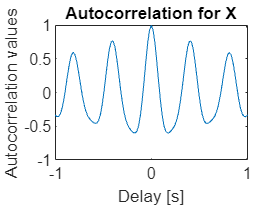

% Wybranie okna autokorelacji (dostosowanie do minimalnej liczby kroków)
window = round(1*fs);
time=linspace(-window, window, 2*window+1)/fs;
point_0 = find(time == 0);

autocorr_x = xcorr(x(11284:11284+round(2*fs)), round(1*fs),'coef');

figure;
plot(time, autocorr_x);
title('Autocorrelation for X');
xlabel('Delay [s]');
ylabel('Autocorrelation values');


point_0_delay = 5;
sub = autocorr_x(point_0+point_0_delay:end);
[max_value, max_index] = max(sub);


samples_diff = max_index+point_0_delay;
step_diff_in_seconds = samples_diff/fs;
step_diff_in_minutes = step_diff_in_seconds/60;
cadence = 1/step_diff_in_minutes

cadence = 143.5415

Kadencja w całym sygnale liczona w kolejnych oknach czasowych

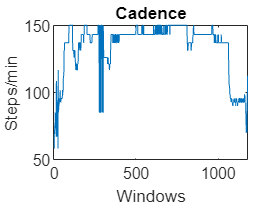

point_0_delay = 20;
overlap = 30;
cadence = zeros(int8(length(x)/overlap), 1);
i_value = 1:overlap:length(x)-2*round(2*fs);

for i = 1:numel(i_value)
    autocorr_x = xcorr(x(i_value(i):i_value(i)+round(2*fs)), round(1*fs),'coef');
    [max_value, max_index] = max(autocorr_x(point_0+point_0_delay:end));
    samples_diff = max_index+point_0_delay;
    step_diff_in_seconds = samples_diff/fs;
    step_diff_in_minutes = step_diff_in_seconds/60;
    cadence(i) = 1/step_diff_in_minutes;
end

figure
plot(cadence)
title('Cadence');
xlabel('Windows');
ylabel('Steps/min');